# Hierachical NSOLT dictionary learning 

Please do not forget to run** setpath **in the top directory of this package, and then return to this directory.

Requirements: MATLAB R2021a

 Contact address: Shogo MURAMATSU,

        Faculty of Engineering, Niigata University,

        8050 2-no-cho Ikarashi, Nishi-ku,

        Niigata, 950-2181, JAPAN

        [http://msiplab.eng.niigata-u.ac.jp](http://msiplab.eng.niigata-u.ac.jp)  

 Copyright (c) 2020, Shogo MURAMATSU, All rights reserved.

## Preparation

clear 
close all
support.fcn_download_img

lena.png already exists in ./data/
baboon.png already exists in ./data/
goldhill.png already exists in ./data/
barbara.png already exists in ./data/


## Bivariate lattice-structure oversampled filter banks 

As an example, let us adopt a non-separable oversampled lapped transform (NSOLT) of  type-I with the number of channels (the numbers of even and odd symmetric channels are identical to each other) and polyphase order (even):

        
$$\mathbf{E}(z_\mathrm{v},z_\mathbf{h})
=
\left(\prod_{k_\mathrm{h}=1}^{N_\mathrm{h}/2}
{\mathbf{V}_{2k_\mathrm{h}}^{\{\mathrm{h}\}}}\bar{\mathbf{Q}}(z_\mathrm{h}){\mathbf{V}_{2k_\mathrm{h}-1}^{\{\mathrm{h}\}}}{\mathbf{Q}}(z_\mathrm{h})\right)
%
\left(\prod_{k_{\mathrm{v}}=1}^{N_\mathrm{v}/2}{\mathbf{V}_{2k_\mathrm{v}}^{\{\mathrm{v}\}}}\bar{\mathbf{Q}}(z_\mathrm{v}){\mathbf{V}_{2k_\mathrm{v}-1}^{\{\mathrm{v}\}}}{\mathbf{Q}}(z_\mathrm{v})\right)
%
\mathbf{V}_0\mathbf{E}_0,$$


        
$$\mathbf{R}(z_\mathrm{v},z_\mathbf{h})
=\mathbf{E}^T(z_\mathrm{v}^{-1},z_\mathrm{h}^{-1}),$$


where

- $\mathbf{E}(z_\mathrm{v},z_\mathrm{h})$:  Type-I polyphase matrix of the analysis filter bank

- $\mathbf{R}(z_\mathrm{v},z_\mathrm{h})$: Type-II polyphase matrix in the synthesis filter bank

- $z_d\in\mathbb{C}, d\in\{\mathrm{v},\mathrm{h}\}$: The parameter of Z-transformation direction

- $N_d\in \mathbb{N}, d\in\{\mathrm{v},\mathrm{h}\}$: Polyphase order in direction $d$ (number of overlapping blocks)

- $\mathbf{V}_0=\left(\begin{array}{cc}\mathbf{W}_{0} & \mathbf{O} \\\mathbf{O} & \mathbf{U}_0\end{array}\right)
%
\left(\begin{array}{c}\mathbf{I}_{M/2} \\ 
\mathbf{O} \\
\mathbf{I}_{M/2} \\
\mathbf{O}
\end{array}\right)\in\mathbb{R}^{P\times M}$,$\mathbf{V}_n^{\{d\}}=\left(\begin{array}{cc}\mathbf{I}_{P/2} & \mathbf{O} \\\mathbf{O} & \mathbf{U}_n^{\{d\}}\end{array}\right)\in\mathbb{R}^{P\times P}, d\in\{\mathrm{v},\mathrm{h}\}$, where$\mathbf{W}_0, \mathbf{U}_0,\mathbf{U}_n^{\{d\}}\in\mathbb{R}^{P/2\times P/2}$are orthonromal matrices.

- $\mathbf{Q}(z)=\mathbf{B}_{P}\left(\begin{array}{cc} \mathbf{I}_{P/2} &  \mathbf{O} \\ \mathbf{O} &  z^{-1}\mathbf{I}_{P/2}\end{array}\right)\mathbf{B}_{P}$, $\bar{\mathbf{Q}}(z)=\mathbf{B}_{P}\left(\begin{array}{cc} z\mathbf{I}_{P/2} &  \mathbf{O} \\ \mathbf{O} &  \mathbf{I}_{P/2}\end{array}\right)\mathbf{B}_{P}$, $\mathbf{B}_{P}=\frac{1}{\sqrt{2}}\left(\begin{array}{cc} \mathbf{I}_{P/2} &  \mathbf{I}_{P/2} \\ \mathbf{I}_{P/2} &  -\mathbf{I}_{P/2}\end{array}\right)$

【References】 

- MATLAB SaivDr Package: [https://github.com/msiplab/SaivDr](https://github.com/msiplab/SaivDr)

- S. Muramatsu, K. Furuya and N. Yuki, "Multidimensional Nonseparable Oversampled Lapped Transforms: Theory and Design," in IEEE Transactions on Signal Processing, vol. 65, no. 5, pp. 1251-1264, 1 March1, 2017, doi: 10.1109/TSP.2016.2633240.

- S. Muramatsu, T. Kobayashi, M. Hiki and H. Kikuchi, "Boundary Operation of 2-D Nonseparable Linear-Phase Paraunitary Filter Banks," in IEEE Transactions on Image Processing, vol. 21, no. 4, pp. 2314-2318, April 2012, doi: 10.1109/TIP.2011.2181527.

- S. Muramatsu, M. Ishii and Z. Chen, "Efficient parameter optimization for example-based design of nonseparable oversampled lapped transform," 2016 IEEE International Conference on Image Processing (ICIP), Phoenix, AZ, 2016, pp. 3618-3622, doi: 10.1109/ICIP.2016.7533034.

- Furuya, K., Hara, S., Seino, K., & Muramatsu, S. (2016). Boundary operation of 2D non-separable oversampled lapped transforms. *APSIPA Transactions on Signal and Information Processing, 5*, E9. doi:10.1017/ATSIP.2016.3.

## Hierachical decomposition for 2-D Grayscale image

Let $R_M^P(\tau)$ be the redundancy of $\tau$-level tree-structured filter bank, then we have the relation 

    
$$R_M^P(\tau)=\left\{\begin{array}{ll} (P-1)\tau + 1, & M=1, \\ \frac{P-1}{M-1}-\frac{P-M}{(M-1)M^\tau}, & M\geq 2.\end{array}\right.$$


% Decimation factor (Strides)
decFactor = [2 2]; % [My Mx]

% Number of channels ( sum(nChannels) >= prod(decFactors) )
nChannels = [1 1] * 4% [Ps Pa] (Ps=Pa)

nChannels =      4     4


% Number of tree levels
nLevels = 3

nLevels = 3


% Redundancy
P = sum(nChannels);
M = prod(decFactor);
redundancy = ...
    (prod(decFactor)==1)*((P-1)*nLevels+1) + ...
    (prod(decFactor)>1)*((P-1)/(M-1)-(P-M)/((M-1)*M^nLevels))

redundancy = 2.3125


% Polyphase Order
ppOrder = [1 1] *4

ppOrder =      4     4



% Sparsity ratio
sparsityRatio = 1/8;

% Number of patchs per image
nSubImgs = 128;

% No DC-leakage
noDcLeakage = true

noDcLeakage = logical
   1



% Seialize
isSerialized = false

isSerialized = logical
   0


Setting of dictionary update step

% Number of iterations
nIters = 5;

% Standard deviation of initial angles
stdInitAng = pi/6; 

% Patch size for training
szPatchTrn = [64 64]; % > [ (Ny+1)My (Nx+1)Mx ]

% Training options
opts = trainingOptions('sgdm', ... % Stochastic gradient descent w/ momentum
    ...'Momentum', 0.9000,...
    ...'InitialLearnRate',0.0100,...
    ...'LearnRateScheduleSettings','none',...
    'L2Regularization',0.0,...1.0000e-04,... % Set zero since parameters are rotaion angles.
    ...'GradientThresholdMethod','l2norm',...
    ...'GradientThreshold',Inf,...
    'MaxEpochs',16,...30,...
    'MiniBatchSize',16,...128,...
    'Verbose',1,...
    'VerboseFrequency',32,...50,...
    ...'ValidationData',[],...
    ...'ValidationFrequency',50,...
    ...'ValidationPatience',Inf,...
    ...'Shuffle','once',...
    ...'CheckpointPath','',...
    ...'ExecutionEnvironment','auto',...
    ...'WorkerLoad',[],...
    ...'OutputFcn',[],...
    'Plots','none',...'training-progress',...
    ...'SequenceLength','longest',...
    ...'SequencePaddingValue',0,...
    ...'SequencePaddingDirection','right',...
    ...'DispatchInBackground',0,...
    'ResetInputNormalization',0);...1

## Construction of layers

import saivdr.dcnn.*
[analysislgraph,synthesislgraph] = fcn_creatensoltlgraphs2d(...
    'NumberOfChannels',nChannels,...
    'DecimationFactor',decFactor,...
    'PolyPhaseOrder',ppOrder,...
    'NumberOfLevels',nLevels,...
    'NumberOfVanishingMoments',noDcLeakage);

[analysislgraph,synthesislgraph] = fcn_replaceinputlayers(...
    analysislgraph,synthesislgraph,szPatchTrn);


### Serialization of subband images

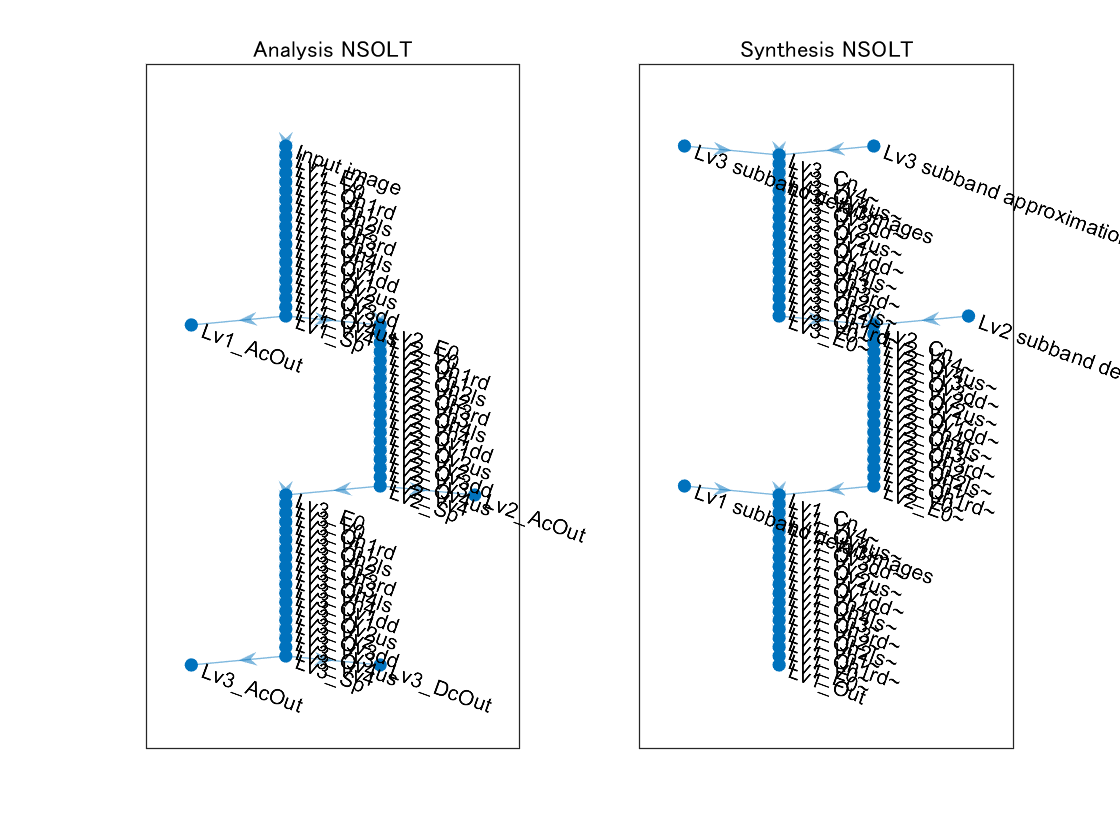

if isSerialized
    [analysislgraph,synthesislgraph] = fcn_attachserializationlayers(...
        analysislgraph,synthesislgraph,szPatchTrn);
end

figure(3)
subplot(1,2,1)
plot(analysislgraph)
title('Analysis NSOLT')
subplot(1,2,2)
plot(synthesislgraph)
title('Synthesis NSOLT')

% Construction of deep learning network.
analysisnet = dlnetwork(analysislgraph);
synthesisnet = dlnetwork(synthesislgraph);

% Initialize
nLearnables = height(synthesisnet.Learnables);
for iLearnable = 1:nLearnables
    synthesisnet.Learnables.Value(iLearnable) = ...
    cellfun(@(x) x+stdInitAng*randn(), ...
    synthesisnet.Learnables.Value(iLearnable),'UniformOutput',false);
end
analysisnet = fcn_cpparamssyn2ana(analysisnet,synthesisnet);

### Confirmation of the adjoint relation (perfect reconstruction)

if isSerialized
    nOutputs = 1;
else
    nOutputs = nLevels+1;
end
x = rand(szPatchTrn,'single');
dls = cell(1,nOutputs);
dlx = dlarray(x,'SSCB'); % Deep learning array (SSCB: Spatial,Spatial,Channel,Batch)
[dls{1:nOutputs}] = analysisnet.predict(dlx);
dly = synthesisnet.predict(dls{1:nOutputs});
display("MSE: " + num2str(mse(dlx,dly)))

    "MSE: 4.8942e-11"



### Initial state of the atomic images

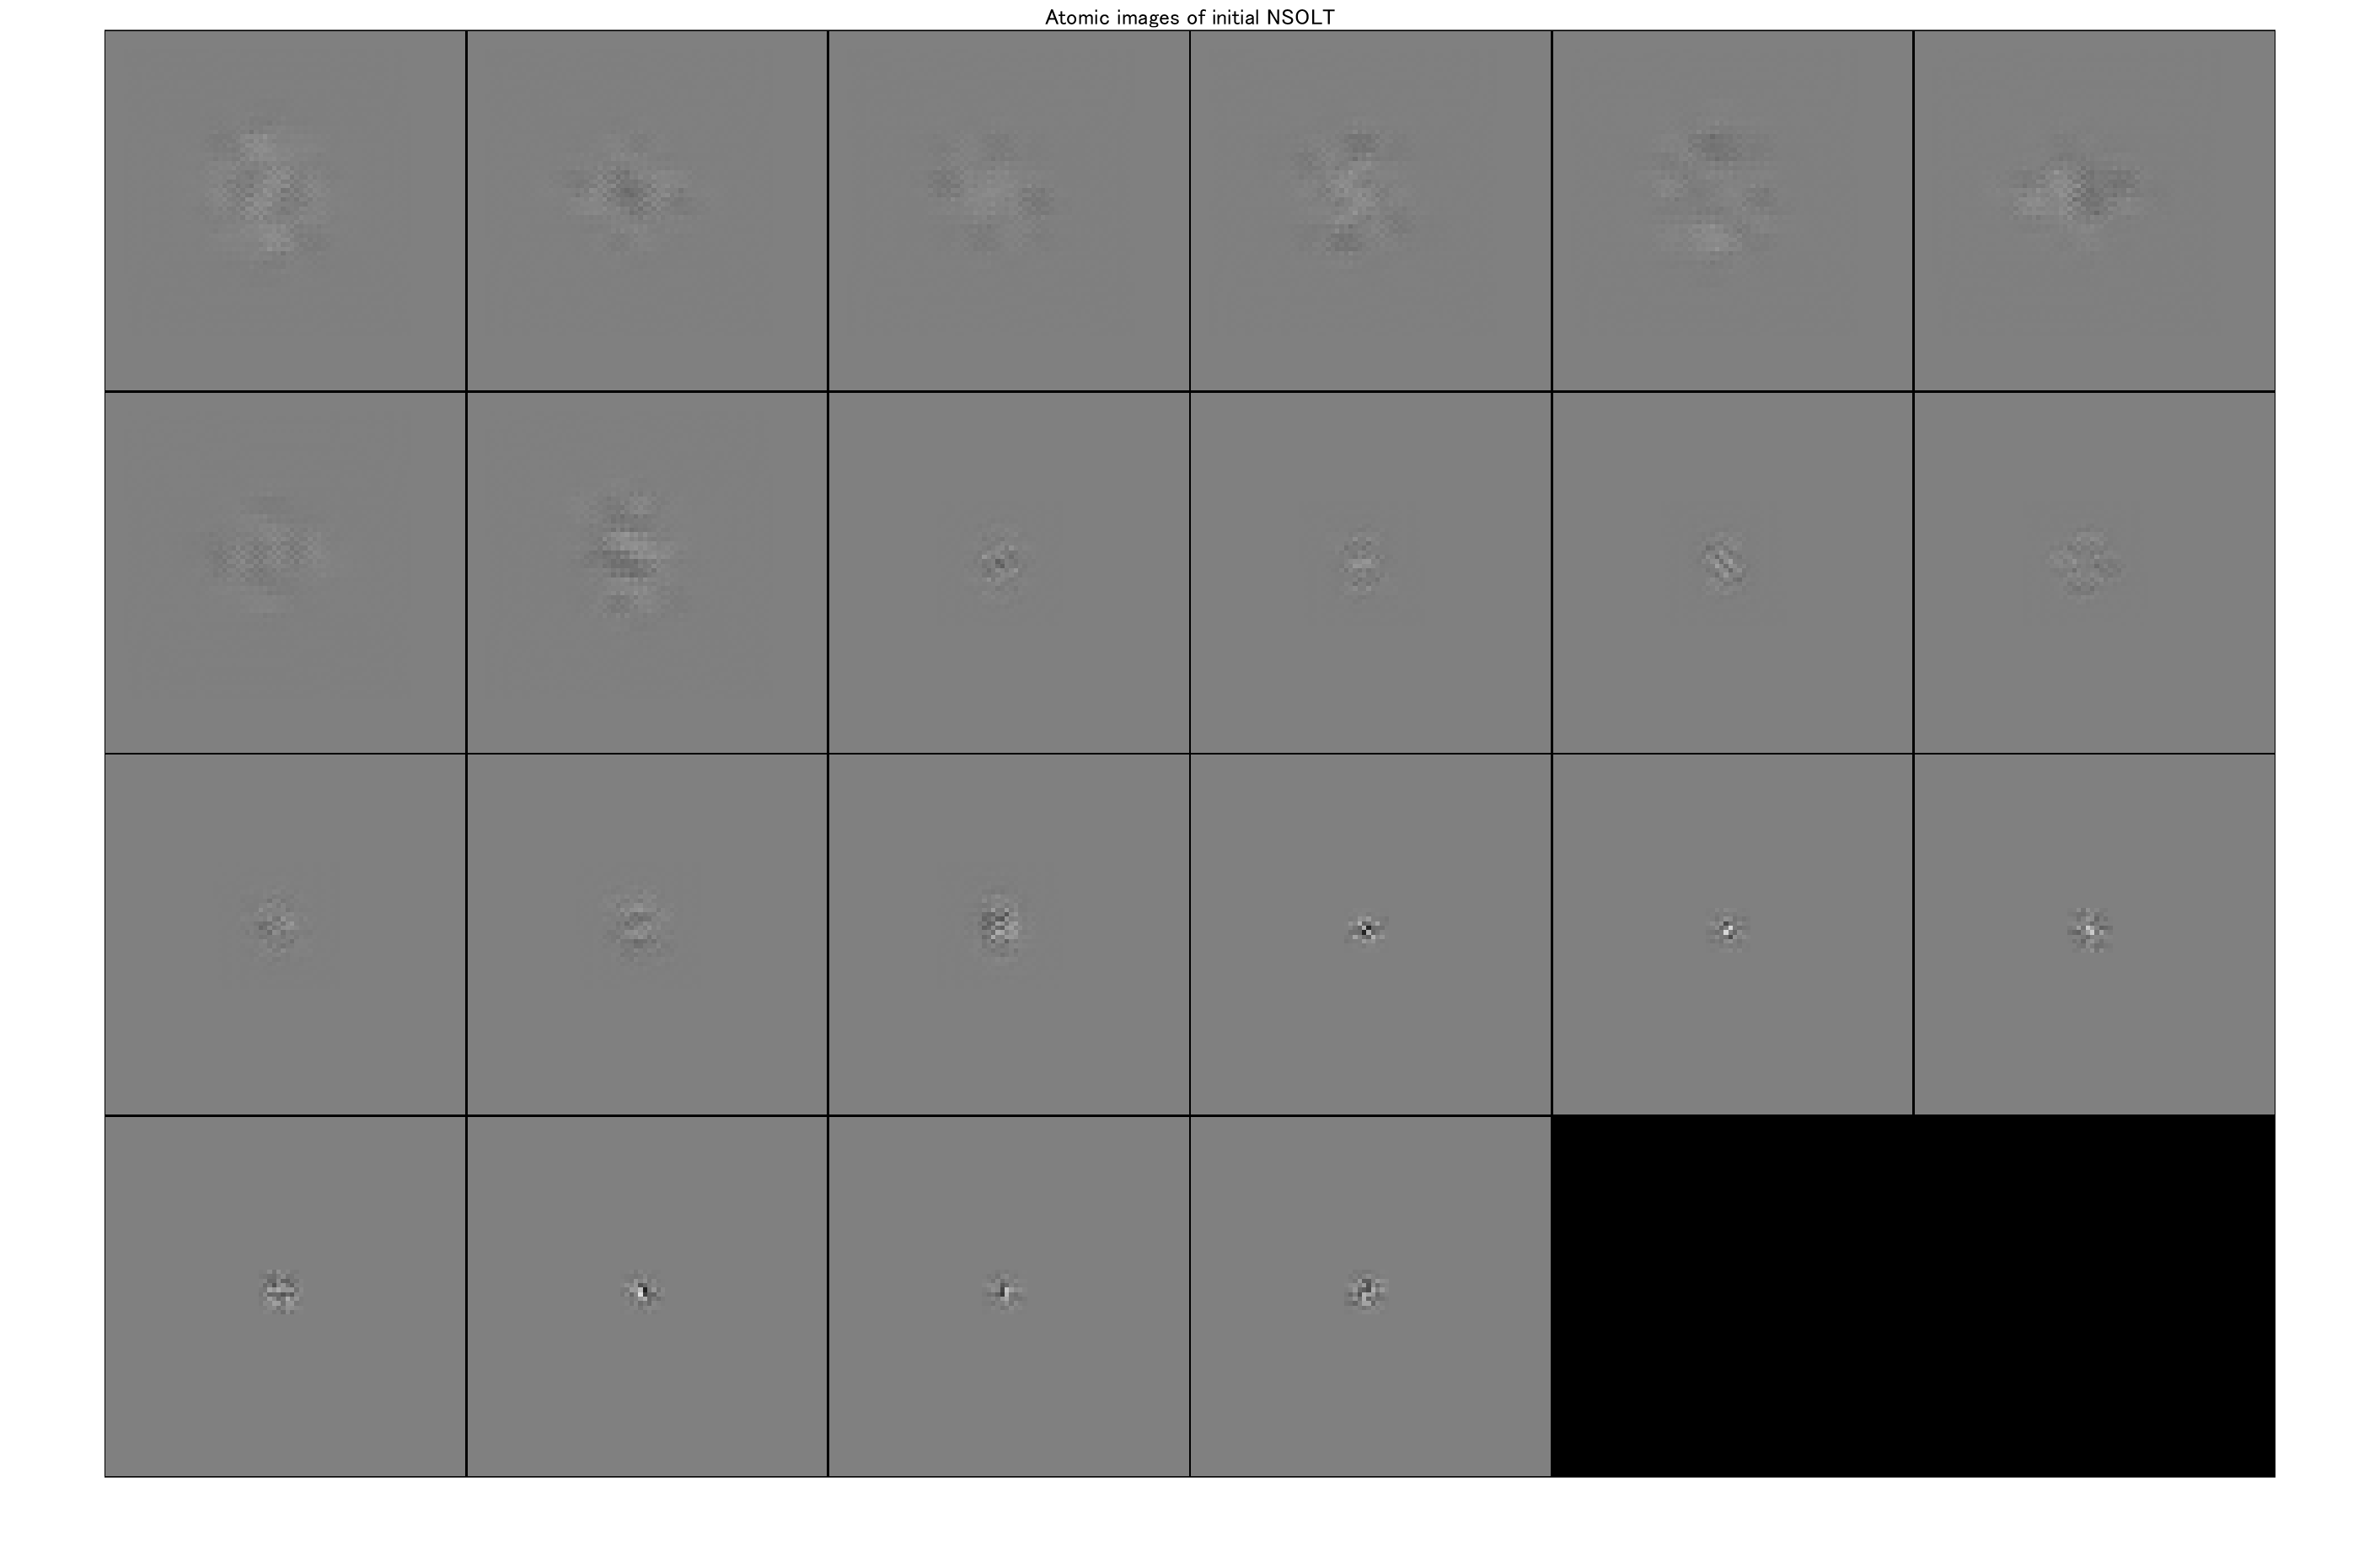

figure(4)
atomicimshow(synthesisnet)
title('Atomic images of initial NSOLT')

### Preparation of traning image

Randomly extracting patches from the image data store

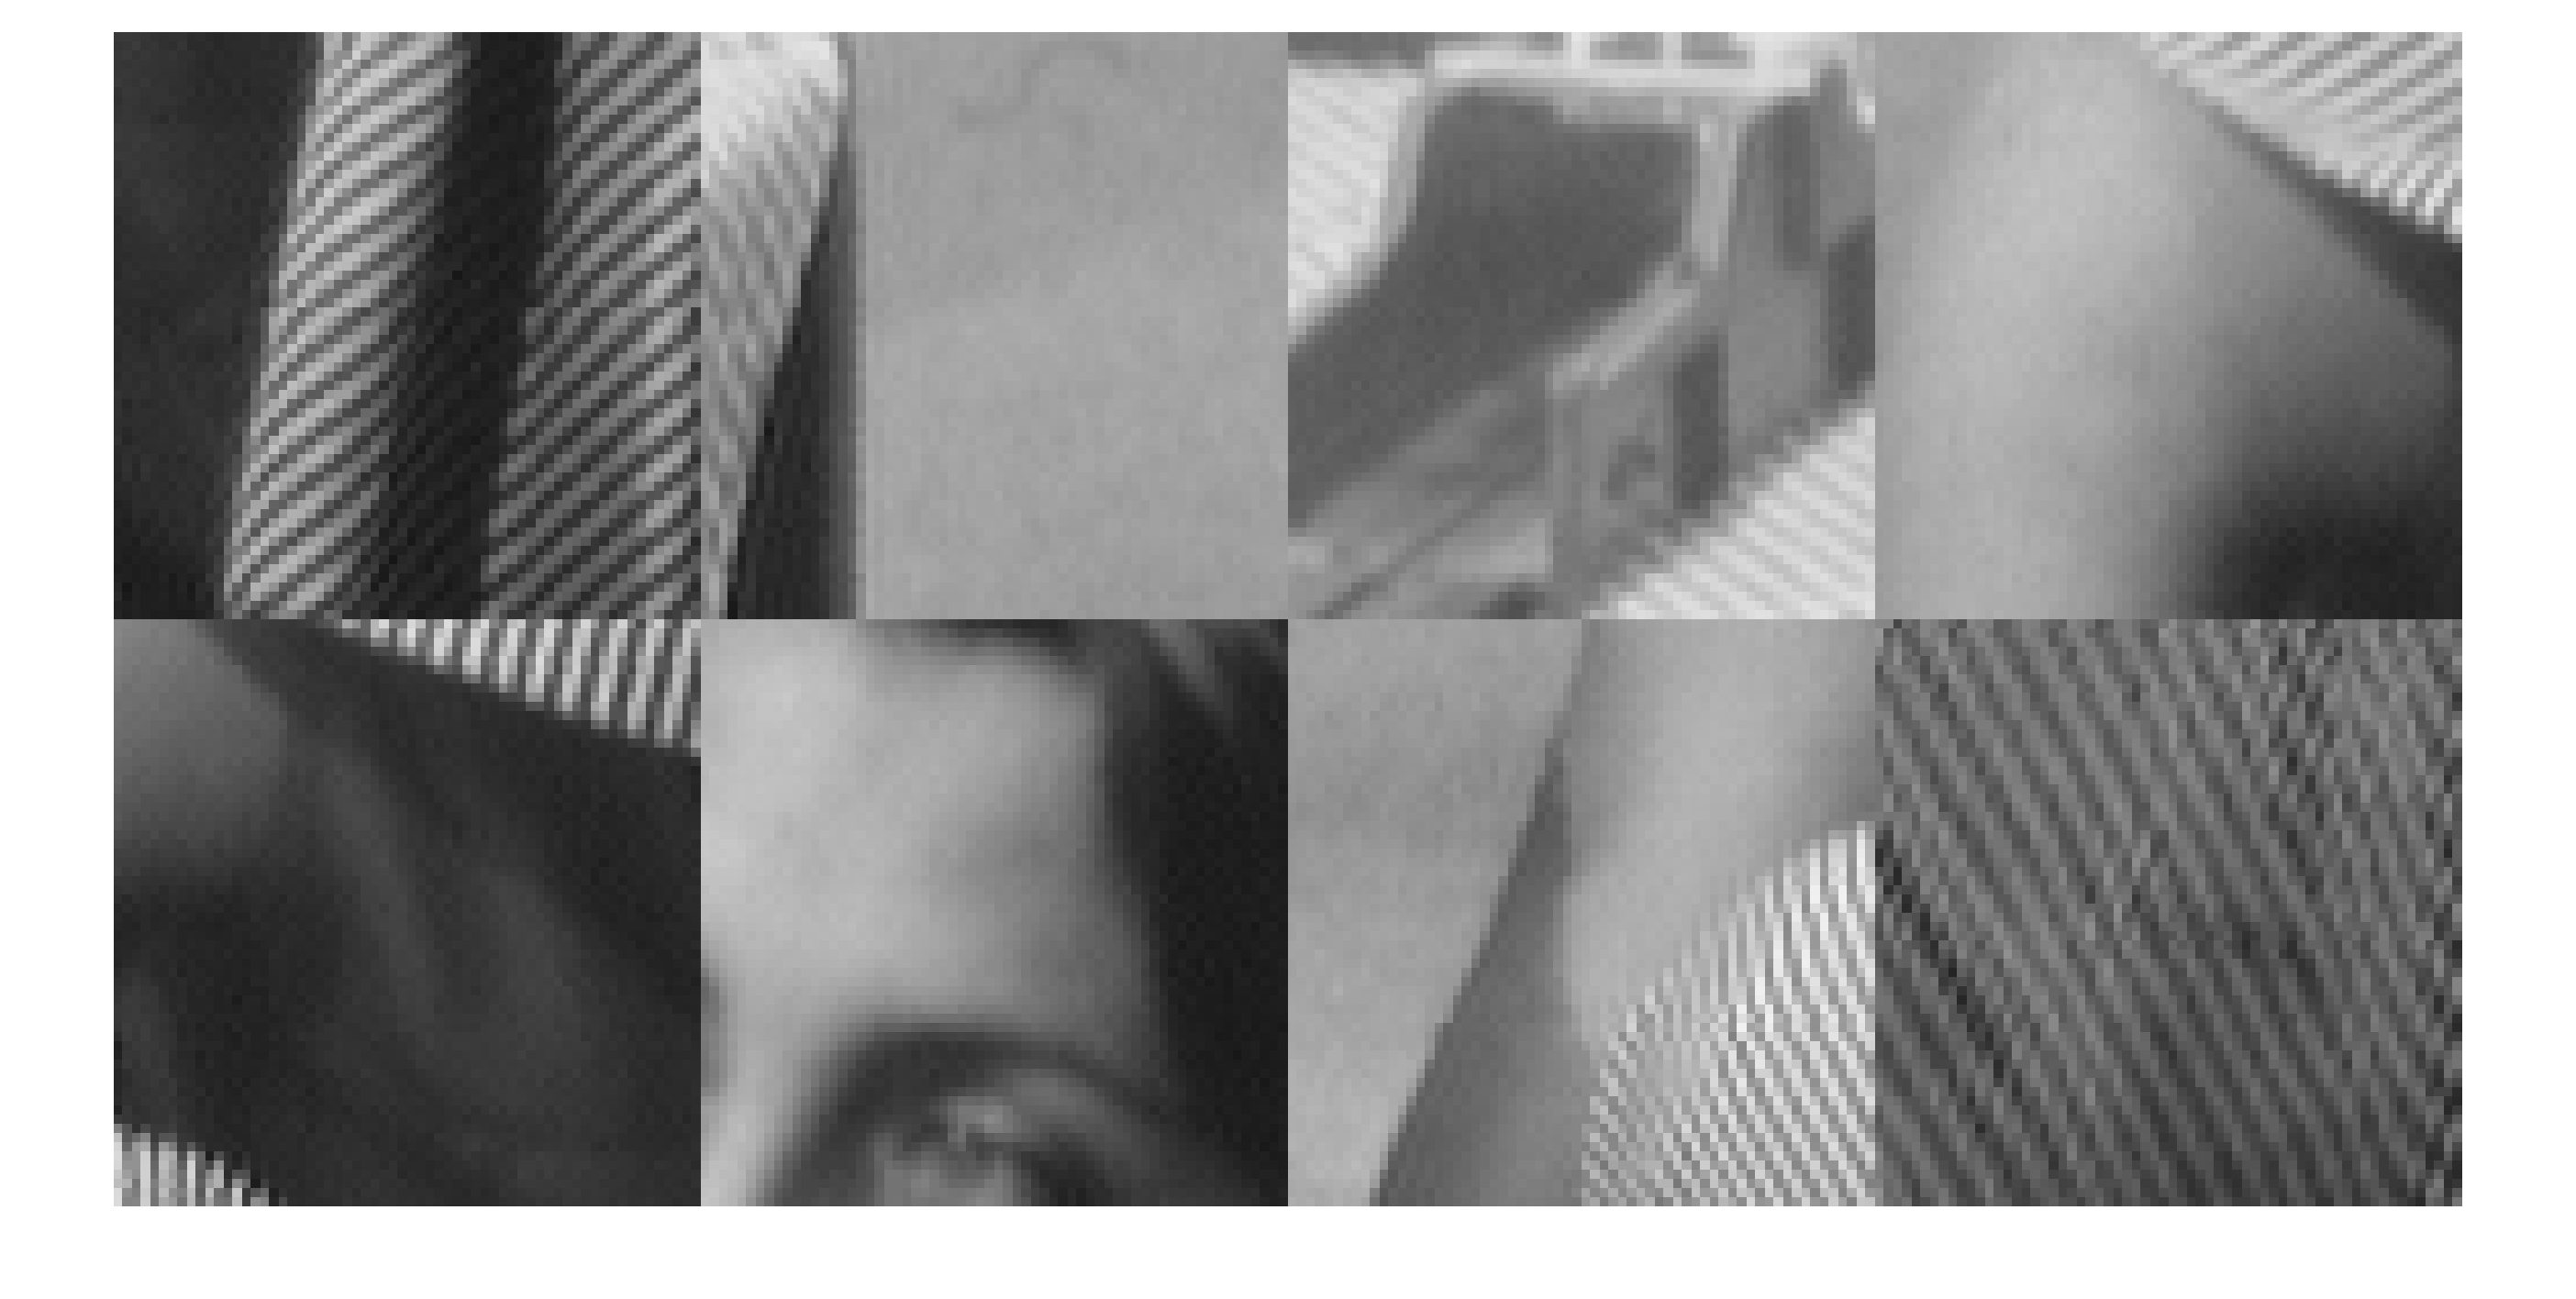

imds = imageDatastore("./data/barbara.png","ReadFcn",@(x) im2single(imread(x)));
patchds = randomPatchExtractionDatastore(imds,imds,szPatchTrn,'PatchesPerImage',nSubImgs);
figure(5)
minibatch = preview(patchds);
responses = minibatch.ResponseImage;
montage(responses,'Size',[2 4]);

### Convolutional dictionary learning

#### Problem setting:

    
$$\{\hat{\mathbf{\theta}},\{ \hat{\mathbf{s}}_n \}\}=\arg\min_{\{\mathbf{\theta},\{\mathbf{s}_n\}\}}\frac{1}{2S}\sum_{n=1}^{S}\|\mathbf{v}_n-\mathbf{D}_{\mathbf{\theta}}\hat{\mathbf{s}}_n\|_2^2,\ \quad\mathrm{s.t.}\ \forall n, \|\mathbf{s}_n\|_0\leq K,$$$


where $\mathbf{D}_{\mathbf{\theta}}$ is a convolutional dictionary with the design parameter vector $\mathbf{\theta}}$.

#### Algorithm:

Iterate the sparse approximation step and the dictionary update step.

- Sparse approximation step

                
$$\hat{\mathbf{s}}_n=\arg\min_{\mathbf{s}_n}\frac{1}{2} \|\mathbf{v}_n-\hat{\mathbf{D}}\mathbf{s}_n\|_2^2\ \quad \mathrm{s.t.}\ \|\mathbf{s}_n\|_0\leq K$$


- Dictionary update step

                
$$\hat{\mathbf{\theta}}=\arg\min_{\mathbf{\theta}}\frac{1}{2S}\sum_{n=1}^{S}\|\mathbf{v}_n-\mathbf{D}_{\mathbf{\theta}}\hat{\mathbf{s}}_n\|_2^2$$


                
$$\hat{\mathbf{D}}=\mathbf{D}_{\hat{\mathbf{\theta}}$$


#### Alternate iteration of sparse approximation step and dictioary update step

- Sparse approximation：Iterative hard thresholding

- Dictionary update： Stochastic gradient descent w/ momentum

% Check if IHT works for dlarray
%x = dlarray(randn(szPatchTrn,'single'),'SSCB');
%[y,coefs{1:nOutputs}] = iht(x,analysisnet,synthesisnet,sparsityRatio);

Iterative calculation of alternative steps

%profile on
for iIter = 1:nIters
    
    % Sparse approximation (Applied to produce an object of TransformedDatastore)
    coefimgds = transform(patchds, @(x) iht4inputimage(x,analysisnet,synthesisnet,sparsityRatio));
    
    % Synthesis dictionary update
    trainlgraph = synthesislgraph.replaceLayer('Lv1_Out',regressionLayer('Name','regression output'));
    synthesisdagnet = trainNetwork(coefimgds,trainlgraph,opts);

    % Analysis dictionary update (Copy parameters from synthesizer to
    % analyzer)
    synthesislgraph = layerGraph(synthesisdagnet); 
    synthesislgraph = synthesislgraph.replaceLayer('regression output',...
        saivdr.dcnn.nsoltIdentityLayer('Name','Lv1_Out'));
    synthesisnet = dlnetwork(synthesislgraph);
    analysisnet = fcn_cpparamssyn2ana(analysisnet,synthesisnet);
    
    % Check the adjoint relation (perfect reconstruction)
    x = rand(szPatchTrn,'single');
    dlx = dlarray(x,'SSCB'); % Deep learning array (SSCB: Spatial,Spatial,Channel,Batch)
    [dls{1:nOutputs}] = analysisnet.predict(dlx);
    dly = synthesisnet.predict(dls{1:nOutputs});
    display("MSE: " + num2str(mse(dlx,dly)))
    
end
%profile off
%profile viewer

単一の GPU で学習中。
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　エポック　　｜　　反復　　｜　　　　　経過時間　　　　　｜　　ミニバッチ　ＲＭＳＥ　　｜　　ミニバッチ損失　　｜　　基本学習率　　｜
｜　　　　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　　　｜　　　　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　　　　１　｜　　　　１　｜　　　　　００：０７：３６　｜　　　　　　　　　７．８１　｜　　　　　　３０．５　｜　　０．０１００　｜
｜　　　　　　４　｜　　　３２　｜　　　　　００：２０：０８　｜　　　　　　　　　４．８７　｜　　　　　　１１．９　｜　　０．０１００　｜
｜　　　　　　８　｜　　　６４　｜　　　　　００：３７：４６　｜　　　　　　　　　４．２３　｜　　　　　　　８．９　｜　　０．０１００　｜
｜　　　　　１２　｜　　　９６　｜　　　　　００：５２：２４　｜　　　　　　　　　３．４９　｜　　　　　　　６．１　｜　　０．０１００　｜
｜　　　　　１６　｜　　１２８　｜　　　　　０１：２５：５９　｜　　　　　　　　　３．５７　｜　　　　　　　６．４　｜　　０．０１００　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜


    "MSE: 3.935e-11"



単一の GPU で学習中。
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　エポック　　｜　　反復　　｜　　　　　経過時間　　　　　｜　　ミニバッチ　ＲＭＳＥ　　｜　　ミニバッチ損失　　｜　　基本学習率　　｜
｜　　　　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　　　｜　　　　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　　　　１　｜　　　　１　｜　　　　　００：０６：５５　｜　　　　　　　　　２．５１　｜　　　　　　　３．２　｜　　０．０１００　｜
｜　　　　　　４　｜　　　３２　｜　　　　　００：１７：０６　｜　　　　　　　　　３．３５　｜　　　　　　　５．６　｜　　０．０１００　｜
｜　　　　　　８　｜　　　６４　｜　　　　　００：３３：５９　｜　　　　　　　　　２．９９　｜　　　　　　　４．５　｜　　０．０１００　｜
｜　　　　　１２　｜　　　９６　｜　　　　　００：５８：１２　｜　　　　　　　　　２．９６　｜　　　　　　　４．４　｜　　０．０１００　｜
｜　　　　　１６　｜　　１２８　｜　　　　　０１：２５：２８　｜　　　　　　　　　３．３８　｜　　　　　　　５．７　｜　　０．０１００　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜


    "MSE: 3.6336e-11"



単一の GPU で学習中。
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　エポック　　｜　　反復　　｜　　　　　経過時間　　　　　｜　　ミニバッチ　ＲＭＳＥ　　｜　　ミニバッチ損失　　｜　　基本学習率　　｜
｜　　　　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　　　｜　　　　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　　　　１　｜　　　　１　｜　　　　　００：０８：３９　｜　　　　　　　　　２．２４　｜　　　　　　　２．５　｜　　０．０１００　｜
｜　　　　　　４　｜　　　３２　｜　　　　　００：２８：５９　｜　　　　　　　　　２．７５　｜　　　　　　　３．８　｜　　０．０１００　｜
｜　　　　　　８　｜　　　６４　｜　　　　　０１：１０：４６　｜　　　　　　　　　２．７３　｜　　　　　　　３．７　｜　　０．０１００　｜
｜　　　　　１２　｜　　　９６　｜　　　　　０１：２９：２１　｜　　　　　　　　　２．４４　｜　　　　　　　３．０　｜　　０．０１００　｜
｜　　　　　１６　｜　　１２８　｜　　　　　０１：４８：３７　｜　　　　　　　　　３．１５　｜　　　　　　　４．９　｜　　０．０１００　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜


    "MSE: 3.7871e-11"



単一の GPU で学習中。
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　エポック　　｜　　反復　　｜　　　　　経過時間　　　　　｜　　ミニバッチ　ＲＭＳＥ　　｜　　ミニバッチ損失　　｜　　基本学習率　　｜
｜　　　　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　　　｜　　　　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　　　　１　｜　　　　１　｜　　　　　００：０７：０８　｜　　　　　　　　　２．８７　｜　　　　　　　４．１　｜　　０．０１００　｜
｜　　　　　　４　｜　　　３２　｜　　　　　００：１８：３９　｜　　　　　　　　　２．２８　｜　　　　　　　２．６　｜　　０．０１００　｜
｜　　　　　　８　｜　　　６４　｜　　　　　００：３４：４７　｜　　　　　　　　　３．２５　｜　　　　　　　５．３　｜　　０．０１００　｜
｜　　　　　１２　｜　　　９６　｜　　　　　００：４９：２４　｜　　　　　　　　　２．１３　｜　　　　　　　２．３　｜　　０．０１００　｜
｜　　　　　１６　｜　　１２８　｜　　　　　０１：０４：１６　｜　　　　　　　　　１．７６　｜　　　　　　　１．６　｜　　０．０１００　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜


    "MSE: 4.6848e-11"



単一の GPU で学習中。
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　エポック　　｜　　反復　　｜　　　　　経過時間　　　　　｜　　ミニバッチ　ＲＭＳＥ　　｜　　ミニバッチ損失　　｜　　基本学習率　　｜
｜　　　　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　　　｜　　　　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　　　　１　｜　　　　１　｜　　　　　１２：４１：２６　｜　　　　　　　　　２．４２　｜　　　　　　　２．９　｜　　０．０１００　｜
｜　　　　　　４　｜　　　３２　｜　　　　　１２：５４：５２　｜　　　　　　　　　２．２９　｜　　　　　　　２．６　｜　　０．０１００　｜
｜　　　　　　８　｜　　　６４　｜　　　　　１３：１４：５４　｜　　　　　　　　　３．１１　｜　　　　　　　４．８　｜　　０．０１００　｜
｜　　　　　１２　｜　　　９６　｜　　　　　１３：３７：３９　｜　　　　　　　　　２．１３　｜　　　　　　　２．３　｜　　０．０１００　｜
｜　　　　　１６　｜　　１２８　｜　　　　　１３：５６：５２　｜　　　　　　　　　１．９３　｜　　　　　　　１．９　｜　　０．０１００　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜


    "MSE: 2.8388e-11"



### The atomic images of trained dictionary

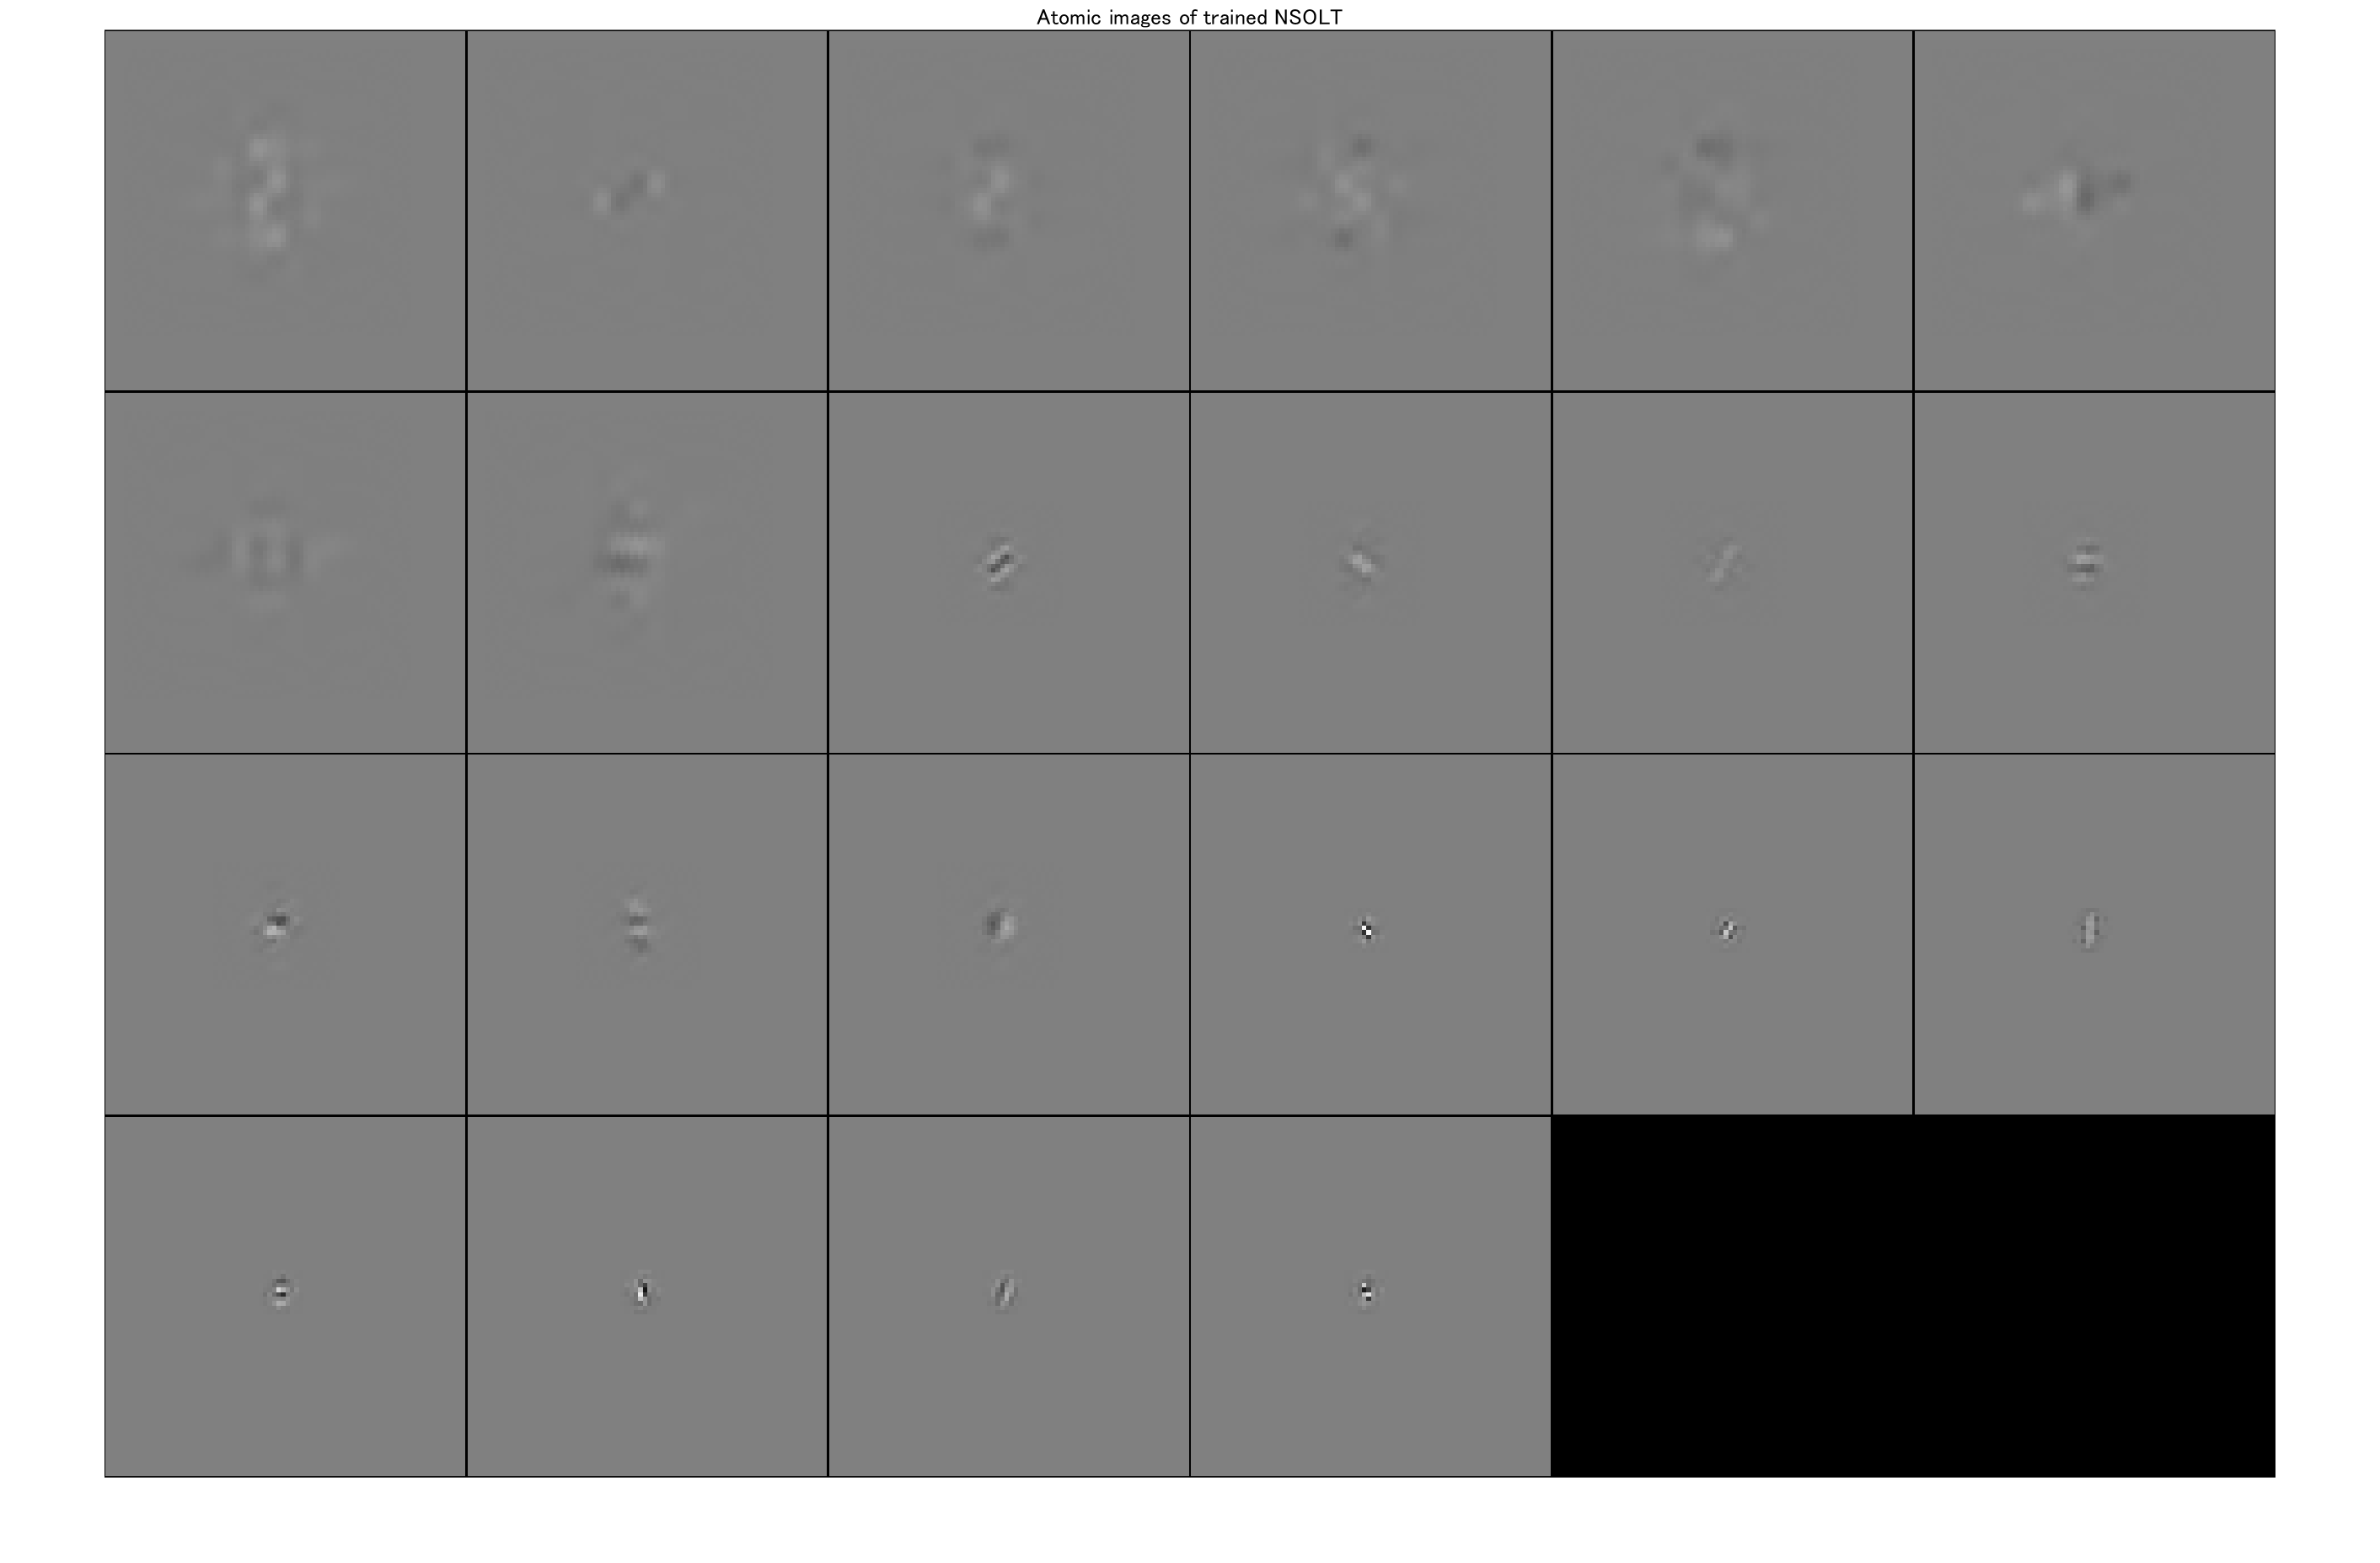

figure(6)
atomicimshow(synthesisnet)
title('Atomic images of trained NSOLT')

### Save the designed network

analysisnet = fcn_cpparamssyn2ana(analysisnet,synthesisnet);
save(sprintf('./data/nsoltdictionary_%s',datetime('now','Format','yyyyMMddhhmmssSSS')),'analysisnet','synthesisnet')

### Function of iterative hard thresholding

The input images of the patch pairs are replaced with sparse coefficients obtained by IHT, where normalization is omitted for the Parseval tight property of NSOLT ( $\mathbf{DD}^T=\mathbf{I}$ ).

         
$$\mathbf{s}^{(t+1)}\leftarrow \mathcal{H}_{T_K}\left(\mathbf{s}^{(t)}-\gamma \hat{\mathbf{D}}^T\left(\hat{\mathbf{D}}\mathbf{s}^{(t)}-\mathbf{v}\right)\right)$$


        
$$t\leftarrow t+1$$


where

        
$$[\mathcal{H}_{T_K}(\mathbf{x})]_i=\left\{\begin{array}{ll} 0 , & |[\mathbf{x}]_i| \leq T_K \\ [\mathbf{x}]_i, & |[\mathbf{x}]_i|> T_K \end{array}\right.$$


【Reference】

-  T. Blumensath and M. E. Davies, "Normalized Iterative Hard Thresholding: Guaranteed Stability and Performance," in IEEE Journal of Selected Topics in Signal Processing, vol. 4, no. 2, pp. 298-309, April 2010, doi: 10.1109/JSTSP.2010.2042411.

function newdata = iht4inputimage(oldtbl,analyzer,synthesizer,sparsityRatio)
% IHT for InputImage in randomPatchExtractionDatastore
%
persistent nInputs
if isempty(nInputs)
    nInputs = 0;
    nLayers = length(synthesizer.Layers);
    for iLayer = 1:nLayers
        layerName = synthesizer.Layers(iLayer).Name;
        if contains(layerName, 'subband detail images' ) || ...
                contains(layerName, 'subband approximation image') || ...
                contains(layerName, 'Sb_Dsz' )
        nInputs = nInputs + 1;
        end
    end
end

% Loop to apply IHT process for every input patch
restbl = removevars(oldtbl,'InputImage');
nImgs = length(oldtbl.InputImage);
coefs = cell(nImgs,nInputs);
for iImg = 1:nImgs
    v = dlarray(oldtbl.InputImage{iImg},'SSCB');
    [~,coefs{iImg,1:nInputs}] = iht(v,analyzer,synthesizer,sparsityRatio);
end
coefs = cellfun(@(x) extractdata(x),coefs,'UniformOutput',false);
% Output as a cell in order to make multiple-input datastore
newdata = [ coefs table2cell(restbl) ];
end

function [y,varargout] = iht(x,analyzer,synthesizer,sparsityRatio)
% IHT Iterative hard thresholding
%
persistent nInputs
if isempty(nInputs)
    nInputs = 0;
    nLayers = length(synthesizer.Layers);
    for iLayer = 1:nLayers
        layerName = synthesizer.Layers(iLayer).Name;
        if contains(layerName, 'subband detail images' ) || ...
                contains(layerName, 'subband approximation image') || ...
                contains(layerName, 'Sb_Dsz' )
        nInputs = nInputs + 1;
        end
    end
end

% Iterative hard thresholding w/o normalization
% (A Parseval tight frame is assumed)
gamma = (1.-1e-3);
nIters = 10;
nCoefs = floor(sparsityRatio*numel(x));
[coefs{1:nInputs}] = analyzer.predict(dlarray(zeros(size(x),'like',x),'SSCB'));
% IHT
for iter=1:nIters
    % Gradient descent
    y = synthesizer.predict(coefs{1:nInputs});
    [grad{1:nInputs}] = analyzer.predict(y-x);
    coefs = cellfun(@(x,y) x-gamma*y,coefs,grad,'UniformOutput',false);
    % Hard thresholding
    coefvecs = cellfun(@(x) x(:).',coefs,'UniformOutput',false);
    srzdcoefs = [coefvecs{:}]; 
    srtdcoefs = sort(extractdata(abs(srzdcoefs)),'descend');
    %
    thk = srtdcoefs(nCoefs);
    %checkSparsity =...
    %nnz(extractdata((abs(srzdcoefs)>thk).*srzdcoefs))/numel(x)<=sparsityRatio;
    %assert(checkSparsity)
    %
    coefs = cellfun(@(x) (abs(x)>thk).*x,coefs,'UniformOutput',false);
    %
    %fprintf("IHT(%d) MSE: %6.4f\n",iter,mse(x,y));
end
varargout = coefs;
end

© Copyright, Shogo MURAMATSU, All rights reserved.